% Limpieza
clear all; 
close all; 
clc;

% Condiciones iniciales
x = -1;     % Posición inicial en x (m)
y = -5;     % Posición inicial en y (m)
theta = 0;  % Orientación inicial (rad)

% Historial de pasos (v=1 m/s constante según el enunciado)
pasos = [
    1,  1.432, 0.0,   1.0;
    2,  0.0,   2.513, 1.0;
    3,  1.432, 0.0,   1.0;
    4,  0.0,   2.513, 1.0;
    5,  1.432, 0.0,   1.0;
    6,  0.0,   2.513, 1.0;
    7,  1.432, 0.0,   1.0;
    8,  0.0,   2.513, 1.0;
    9,  1.432, 0.0,   1.0;
    10, 0.0,   2.513, 1.0;
];

% Preparamos la tabla de resultados
resultados = zeros(size(pasos,1)+1, 4);
resultados(1,:) = [0, x, y, theta];

% Simulación paso a paso
for i = 1:size(pasos,1)
    paso = pasos(i,:);
    v = paso(2);
    w = paso(3);
    dt = paso(4);
    
    % Actualización de la orientación
    theta = theta + w*dt;
    
    % Actualización de la posición (integración numérica)
    x = x + v*cos(theta)*dt;
    y = y + v*sin(theta)*dt;
    
    % Guardamos resultados
    resultados(i+1,:) = [paso(1), x, y, theta];
end

% Mostrar tabla de resultados
disp('Tabla de poses del robot:');

Tabla de poses del robot:


disp('Paso      x(m)       y(m)       θ(rad)');

Paso      x(m)       y(m)       θ(rad)


disp(resultados);

         0   -1.0000   -5.0000         0
    1.0000    0.4320   -5.0000         0
    2.0000    0.4320   -5.0000    2.5130
    3.0000   -0.7263   -4.1580    2.5130
    4.0000   -0.7263   -4.1580    5.0260
    5.0000   -0.2845   -5.5201    5.0260
    6.0000   -0.2845   -5.5201    7.5390
    7.0000    0.1591   -4.1586    7.5390
    8.0000    0.1591   -4.1586   10.0520
    9.0000   -1.0003   -4.9990   10.0520
   10.0000   -1.0003   -4.9990   12.5650




% Mostrar pose final
fprintf('\nPose final del robot:\n');


Pose final del robot:


fprintf('x = %.4f m\n', x);

x = -1.0003 m


fprintf('y = %.4f m\n', y);

y = -4.9990 m


fprintf('θ = %.4f rad (%.2f°)\n', theta, rad2deg(theta));

θ = 12.5650 rad (719.92°)


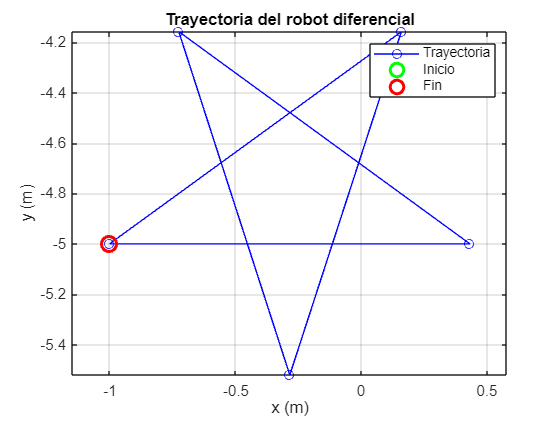


% Gráfica de la trayectoria en 2D
figure;
plot(resultados(:,2), resultados(:,3), 'b-o');
hold on;
plot(resultados(1,2), resultados(1,3), 'go', 'MarkerSize', 10, 'LineWidth', 2); % Punto inicial
plot(resultados(end,2), resultados(end,3), 'ro', 'MarkerSize', 10, 'LineWidth', 2); % Punto final
xlabel('x (m)'); ylabel('y (m)');
title('Trayectoria del robot diferencial');
legend('Trayectoria', 'Inicio', 'Fin');
grid on;
axis equal;

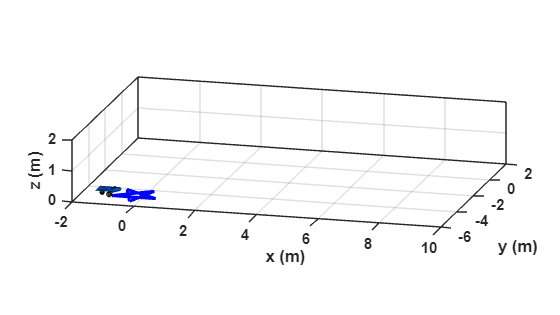


%% Animación en 3D

% Crear escena 3D
scene = figure;
set(scene, 'Color', 'white');
set(gca, 'FontWeight', 'bold');
sizeScreen = get(0, 'ScreenSize');
set(scene, 'position', sizeScreen);
camlight('headlight');
axis equal;
grid on; box on;
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
view([15 15]);
axis([-2 10 -6 2 0 2]);  % Ajusta esto según el rango de movimiento

% Cargar modelo del robot
scale = 4;
MobileRobot_5;  % Asegúrate de tener este archivo en la misma carpeta

% Extraer datos
x_vec = resultados(:,2);
y_vec = resultados(:,3);
theta_vec = resultados(:,4);

% Dibujo inicial
H1 = MobilePlot_4(x_vec(1), y_vec(1), theta_vec(1), scale); hold on;
H2 = plot3(x_vec(1), y_vec(1), 0, 'b', 'LineWidth', 2);

% Animación
for k = 1:length(x_vec)
    delete(H1);
    delete(H2);
    
    H1 = MobilePlot_4(x_vec(k), y_vec(k), theta_vec(k), scale);
    H2 = plot3(x_vec(1:k), y_vec(1:k), zeros(1,k), 'b', 'LineWidth', 2);
    
    pause(0.3);  % Puedes ajustar el tiempo según la velocidad que quieras
end